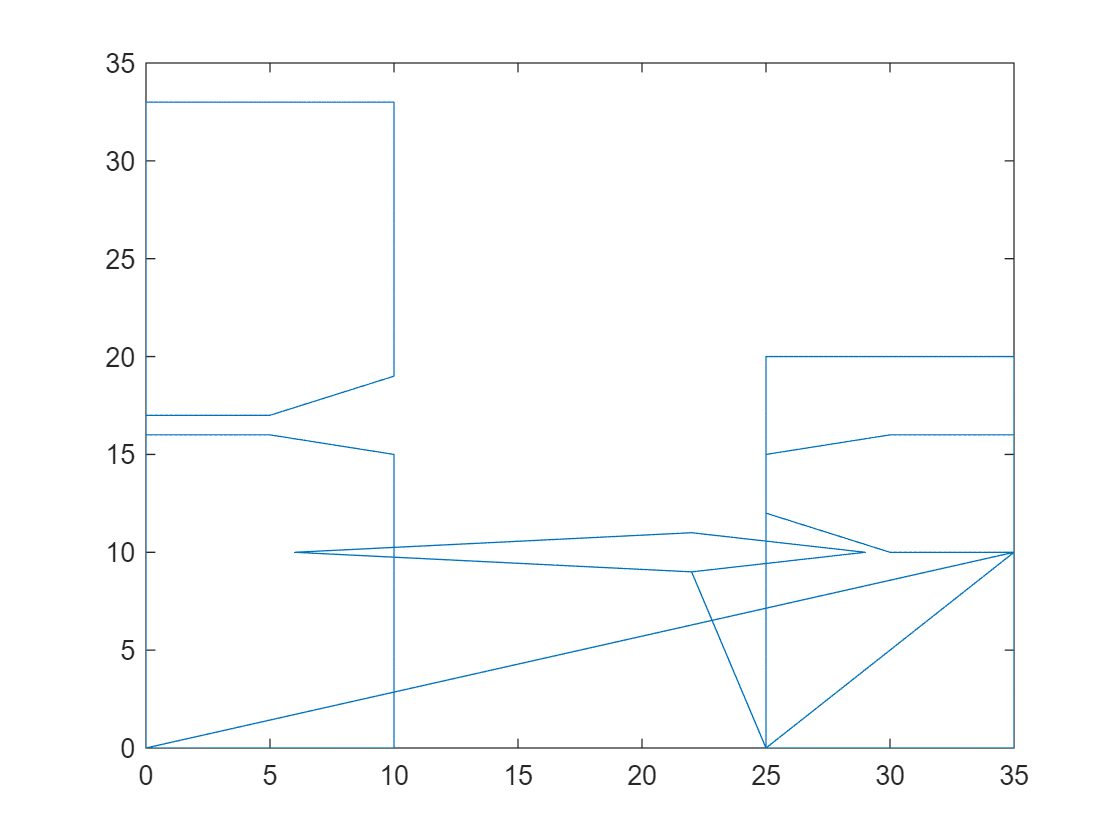

clf
obs_no_circle_trap{1}=[0,17;
        5,17;        
        10,19;
        10,33;
        0,33;
        0,17];
obs_no_circle_trap{2}=[0,0;
        10,0;
        10,15;
        5,16;        
        0,16
        0,0];
obs_no_circle_trap{3}=[
        
        25,10;
        25,20;
        15,20;
        15,12;
        20,10;
        25,10];
obs_no_circle_trap{4}=[15,0;
        25,0;
        25,16;
        20,16;
        15,15;
        15,0];

obs_no_circle_trap{5}=[12+10,9;
                       19+10,10;
                       12+10,11;
                       6,10;
                       12+10,9];
obs_no_circle_trap{3}(:,1)=obs_no_circle_trap{3}(:,1)+10;
obs_no_circle_trap{4}(:,1)=obs_no_circle_trap{4}(:,1)+10;
outline_all_trap=[];
for i=1:length(obs_no_circle_trap)
% plot(obs_no_circle_trap{i}(:,1),obs_no_circle_trap{i}(:,2),'k-');hold on;
for k=1:length(obs_no_circle_trap{i}(:,1))-1
    x_interp = linspace(obs_no_circle_trap{i}(k,1), obs_no_circle_trap{i}(k+1,1), num_steps);
    y_interp = linspace(obs_no_circle_trap{i}(k,2), obs_no_circle_trap{i}(k+1,2), num_steps);
    outline=[x_interp;y_interp]';
    outline=[outline,ones(length(outline(:,1)),1)*i];
    outline_all_trap=[outline_all_trap;outline];
end

end

plot(outline_all_trap(:,1),outline_all_trap(:,2))